# Métodos Numéricos

# Introducción a MATLAB

## Algunos comandos de interés:

>>clc   % Borra lo escrito en la ventana de comandos

>>clear % Borra las variables almacenadas en la memoria

>>close % Sirve para cerrar la última figura o gráfica realizada

>> doc polyfit % doc sirve para buscar información sobre un comando o instrucción. En este caso se buscaría documentación sobre la función polyfit

 >> A\b % instrucción que usa matlab para resolver un sistema de ecuaciones de la forma Ax=b

## Matrices en matlab

A=[1 2 3;-2 3 4; 1 3 5] % Así se ingresa una matriz

A =      1     2     3
    -2     3     4
     1     3     5


Puedo multiplicar por escalar

2*A

ans =      2     4     6
    -4     6     8
     2     6    10


Puedo sumar matrices

A+2*A

Puedo asignar valores a cariables

B=A+2*A

B =      3     6     9
    -6     9    12
     3     9    15


Escalonar matrices

rref(B)

ans =      1     0     0
     0     1     0
     0     0     1


## Calcular el determinante

det(B)

ans = 108.0000

La transpuesta

B'

ans =      3    -6     3
     6     9     9
     9    12    15


Ampliar una matriz

A=2*rand(4,6)-1

A =     0.6704    0.0986    0.5130    0.9455    0.9083   -0.4370
   -0.3551   -0.3392   -0.1722   -0.3445   -0.9362   -0.5392
    0.1045    0.2389   -0.0153    0.6756   -0.2863    0.4223
    0.9583   -0.2787    0.3895    0.4781    0.3253    0.2491


% Con números enteros
A=round(100*rand(5,5))

A =     59    24    14    81    45
    66    72    84    50    96
     5    86    14    49     4
    35    28    59    88    97
    45    73    37    35    19


randi(100,2)

ans =     67    68
    59    37


La inversa:

inv(A)

ans =     0.0145    0.0066   -0.0096   -0.0139    0.0054
    0.0071    0.0210    0.0216   -0.0196   -0.0272
   -0.0372   -0.0460   -0.0372    0.0481    0.0830
   -0.0049   -0.0281   -0.0081    0.0247    0.0293
    0.0198    0.0450    0.0272   -0.0306   -0.0712


Reemplazar una entrada de la matriz por un número

A(4,4)=-1

A =     59    24    14    81    45
    66    72    84    50    96
     5    86    14    49     4
    35    28    59    -1    97
    45    73    37    35    19


A(2,1)=1

A =     59    24    14    81    45
     1    72    84    50    96
     5    86    14    49     4
    35    28    59    -1    97
    45    73    37    35    19


Reemplazar toda una columna

A(:,2)=0

A =     59     0    14    81    45
     1     0    84    50    96
     5     0    14    49     4
    35     0    59    -1    97
    45     0    37    35    19


Suma por filas o columnas

b=sum(A) % Suma las columnas de A

b =    145     0   208   214   261


b=sum(A,2); % suma por filas

Solucionar un sistema de ecuaciones Ax=b

Método 1: Ampliar la matriz, escalonar, interpretar

% Testear un método
A=rand(4,4);
b=sum(A,2); % Ax=b tendrá solución x=
Ampliada=[A b]

Ampliada =     0.6203    0.9748    0.1220    0.1522    1.8693
    0.8112    0.6513    0.2684    0.3480    2.0789
    0.0193    0.2312    0.2578    0.1217    0.6300
    0.0839    0.4035    0.3317    0.8842    1.7032


Escalonada=rref(Ampliada)

Escalonada =     1.0000         0         0         0    1.0000
         0    1.0000         0         0    1.0000
         0         0    1.0000         0    1.0000
         0         0         0    1.0000    1.0000


Luego la solución es x1=1; x2=1; x3=1; x4=1

Método 2. Con la inversa. $Ax=b -->  x=A^{-1}*b$

x=inv(A)*b

x =     1.0000
    1.0000
    1.0000
    1.0000


Método 3: Método back slash "\". Ax=b

x=A\b

x =     1.0000
    1.0000
    1.0000
    1.0000


## Una matriz se puede definir de muchas maneras:

% Escribiendo cada fila y cambiando de fila al usar ";"
A = [1 2 3;4 5 6]
% Usando comandos de generación de matrices que están definidos previamente
% en matlab.
% Por ejemplo ones(n) genera una matriz nxn con unos
B = ones(3)
% Por ejemplo zeros(m,n) genera una matriz mxn con ceros
c = zeros(3,2)
% Por ejemplo "rand(m,n)" genera una matriz mxn donde cada entrada es un
% número aleatorio entre 0 y 1.
d = rand(3,4)
% ¿Qué hace diag? (Recuerda la instrucción >>doc diag)
M = diag(diag(d))

## Un polinomio $a_nx^n+a_{n-1}x^{n-1}+...+a_1x+a_0$ puede representarse en matlab con el vector fila $[a_n, a_{n-1}, ...,a_1,a_0]$

% Ejemplo:
q = [1 -3 2 5]

q =      1    -3     2     5


Representa el polinomio $x^3-3x^2+2x+5$

## La funció polyval sirve para evaluar polinomios. Por ejemplo para evaluar el polinomio anterior en $x=-2$ usamos:

q2 = polyval(q,-2)

q2 = -19

## Una matriz se puede definir de muchas maneras:

% Escribiendo cada fila y cambiando de fila al usar ";"
A = [1 2 3;4 5 6]

A =      1     2     3
     4     5     6


% Usando comandos de generación de matrices que están definidos previamente
% en matlab.
% Por ejemplo ones(n) genera una matriz nxn con unos
B = ones(3)

B =      1     1     1
     1     1     1
     1     1     1


% Por ejemplo zeros(m,n) genera una matriz mxn con ceros
c = zeros(3,2)

c =      0     0
     0     0
     0     0


% Por ejemplo "rand(m,n)" genera una matriz mxn donde cada entrada es un
% número aleatorio entre 0 y 1.
d = rand(3,4)

d =     0.1712    0.2769    0.8235    0.9502
    0.7060    0.0462    0.6948    0.0344
    0.0318    0.0971    0.3171    0.4387


% ¿Qué hace diag? (Recuerda la instrucción >>doc diag)
M = diag(diag(d))

M =     0.1712         0         0
         0    0.0462         0
         0         0    0.3171


## Trabajando con funciones en matlab

Para "cargar" una función en Matlab y poderla seguir usando en evaluaciones o gráficas usamos el comando "@(variable de la función)"

Por ejemplo: la función $f(x)=e^{-x}$ en matlab es:

f = @(x)exp(-x); % Note que exp(.) es la función exponencial en matlab

Es útil dividir un intervalo [a,b] tomando puntos entre a y b que estén equiespaciados. Ese proceso lo hace la función "linspace"

% Ejemplo: Dividamos en el intervalo [-1,2] tomando 5 puntos del intervalo
% equiespaciados e incluyendo los extremos.
x = linspace(-1,2,5)

x =    -1.0000   -0.2500    0.5000    1.2500    2.0000


Puede evaluarse una función en muchos puntos a la vez:

f(x)

ans =     2.7183    1.2840    0.6065    0.2865    0.1353


Un comando útil para graficar es "plot()". Basta darle las coordenadas en x y en y.

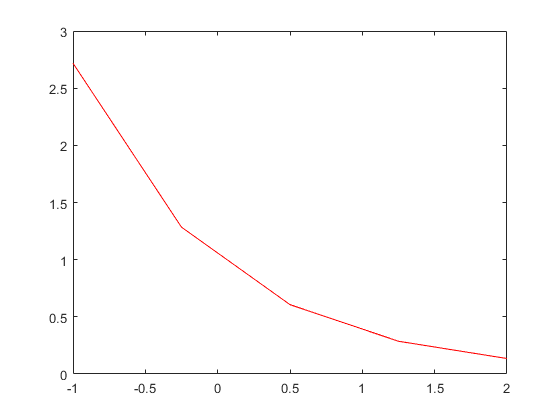

% Ejemplo:
plot(x,f(x),'r')

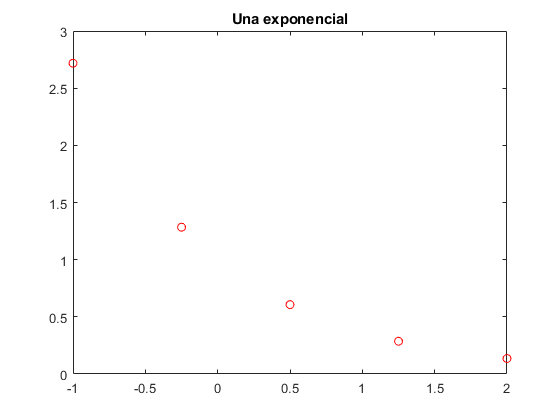


% Puede modificarse sus propiedades
plot(x,f(x),'or')
title ('Una exponencial')

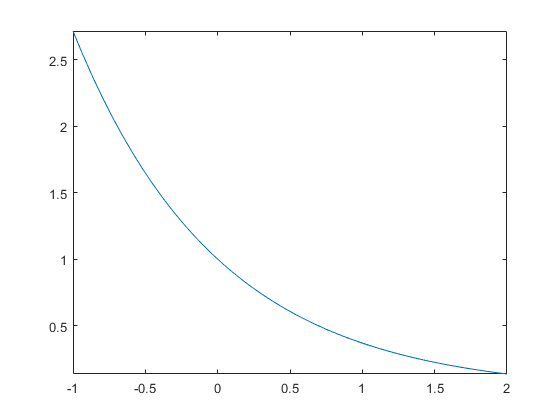

% Un comando mas para graficar "fplot".  Es cuidadoso con las asintotas.
fplot(f,[-1,2])

## Danger: Para evaluación en vectores, coloque el punto "." antes del operador

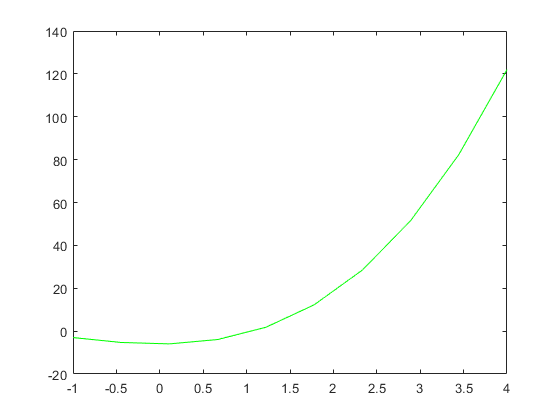

% Ejemplo:
g = @(x) x.^3+4*x.*x- 6;
t=linspace(-1,4,10);
plot(t,g(t),'g')

No usarlo lleva a un error

%g1 = @(x) x^3+4*x*x- 6
 %plot(y,g1(y),'g')


# Más sobre matrices

Descomposición A=D-L-U

 A=[8,3,5; -2,7,3;4,-5,18]

A =      8     3     5
    -2     7     3
     4    -5    18


 % Matriz D
D=diag(diag(A))

D =      8     0     0
     0     7     0
     0     0    18


 % Matriz L
 L=-tril(A,-1)

L =      0     0     0
     2     0     0
    -4     5     0


 % Matriz U
 U=-triu(A,1)

U =      0    -3    -5
     0     0    -3
     0     0     0


 % Matriz de Jacobi
 Tj=inv(D)*(L+U)

Tj =          0   -0.3750   -0.6250
    0.2857         0   -0.4286
   -0.2222    0.2778         0


 b=[21,7,42]'

b =     21
     7
    42


 C=inv(D)*b

C =     2.6250
    1.0000
    2.3333


 % iteración jacobi
 x0=zeros(3,1)

x0 =      0
     0
     0


 x1=Tj*x0+C

x1 =     2.6250
    1.0000
    2.3333


  x2=Tj*x1+C

x2 =     0.7917
    0.7500
    2.0278


Iteracion

   
  x5=Tj*x4+C;
   x2=x3

x2 =     1.1440
    0.3493
    2.1899


    x3=Tj*x2+C;
   x2=x3

x2 =     1.1253
    0.3883
    2.1761
